% 
% Simulation file to run linear CSTR Plant assumming perfect model

clear all
parameters = [102 294 -69.71*10^6 1.205 20.75*10^6 69.71*10^6 8314 801 3137 ...
    851 101 10.1 294 1000 4183 294 340.2 297.1 4.857 0.1377 0.28];

[A,B,C,D] = linearmodSS(parameters);
eig(A)

ans =    -0.0298
   -0.0017
   -0.0013



Aplant = A;
Bplant = B;

sys = ss(A,B,C,D);
Gz = c2d(sys,60);

tzero(sys)

ans = -0.0013

Gz = c2d(sys,60);
stepobj = step(Gz);
[Amod,Bmod,Cz,d] = ssdata(Gz);
Gzpk = zpk(Gz)


Gzpk =
 
   -0.10671 (z+0.5399)
  ---------------------
  (z-0.9051) (z-0.1675)
 
Sample time: 60 seconds
Discrete-time zero/pole/gain model.



Gs = tf(Gz)


Gs =
 
   -0.1067 z - 0.05761
  ----------------------
  z^2 - 1.073 z + 0.1516
 
Sample time: 60 seconds
Discrete-time transfer function.



pole(Gz)

ans =     0.9051
    0.1675
    0.9222


zero(Gz)

ans =    -0.5399
    0.9222


tbeng = 0;
deltaT = 60;

P = input('Prediction Horizon [at least 60 min] ')

P = 60

M = input('Control Horizon [1 to 8] ')

M = 1

rsp = input('Setpoint [0/1/10/20...] ')

rsp = 10

Sf = zeros(P,M); % initial zeros for DMC matrix 

x0 = [0;0;0];
x(:,1) = x0;
y(1) = Cz*x;
Wu = 0;
u_ini = 0;
H = 0;
for j=1:P
    H = H + Cz*Amod^(j-1)*Bmod;
    S(j,1) = H;
    Cphi(j,:) = Cz*Amod^(j); 
end

for j=1:M
    zero_DMC = zeros(j-1,1);
    Sf(:,j) = cat(1,zero_DMC,S(1:end+1-j,1)); %DMC 
end

Kmat = (Sf'*Sf+Wu)\Sf';

## MPC Perfect linear Model

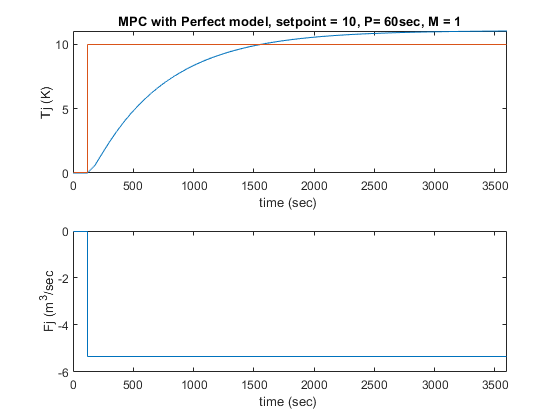


time = tbeng:deltaT:[P*60];

r = [zeros(2,1);ones((P-2),1)];    
        r = r*rsp;
        E = r - S*x0' - Cphi*u_ini;

u_cal = zeros(P,1);   
du = Kmat*E;
u_cal(3:M+2,1) = du(:,1);         
u_cal(M+3:P,1) = zeros(P-M-2,1);
u = cumsum(u_cal); % Control moves


for k = 1:length(time)-1
   
  
[t,xdummy] = ode45(@(t,x) lincstrplant(t,x,Aplant,Bplant,u(k,1)), [time(k) time(k+1)], x0);
x0= xdummy(end,:)'; 
x(:,k+1) = xdummy(end,:);
y(k+1) = Cz*x(:,k+1); 

end
u(k+1) = u(k);
r(k+1) = r(k);

subplot(2,1,1)
plot(time,y)
hold on
stairs(time,r)
hold off
title(['MPC with Perfect model, setpoint = ', num2str(rsp), ', P= ',num2str(P), 'sec, M = ', num2str(M)])
ylabel('Tj (K)')
xlabel('time (sec) ')
xlim([0 3600])

subplot(2,1,2)
stairs(time,u)
ylabel('Fj (m^3/sec')
xlabel('time (sec) ')
xlim([0 3600])

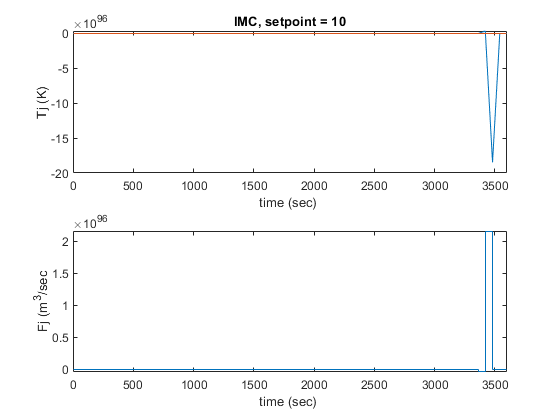

x0 = [0,0,0]; % initial conditions
y2 =  zeros(1,length(time)+2);
ymod = zeros(1,length(time)+2);
r2 = zeros(1,length(time)+2);
rm2 = zeros(1,length(time)+2);
u2 = zeros(1,length(time)+2);

lambda = 10;
alpha = exp(-60/lambda);

for j = 3:length(time)-1 % step change at time = 0
    
    if time(j) < 3
        r2(j+2) = 0;
    else 
        r2(j+2) = 1*rsp;
    end
    ymod(j) = modelresponse(ymod(j-1), ymod(j-2), u2(j-1), u2(j-2));
    d2(j) = y2(j) - ymod(j);
    rm2(j) = r2(j) - d2(j);
    
    u2(j) = IMC(u2(j-1),alpha,rm2(j),rm2(j-1),rm2(j-2));
    
[t,xnew] = ode45(@(t,x) lincstrplant(t,x,Aplant,Bplant,u2(j)), [time(j) time(j)+deltaT], x0);
y2(j+1) = xnew(end,end); 
x0= xnew(end,:)'; 
end

subplot(2,1,1)
plot(time,y2(3:end))
hold on
stairs(time,r2(3:end))
hold off
title(['IMC, setpoint = ', num2str(rsp),])
ylabel('Tj (K)')
xlabel('time (sec) ')
xlim([0 3600])

subplot(2,1,2)
stairs(time,u2(3:end))
ylabel('Fj (m^3/sec')
xlabel('time (sec) ')
xlim([0 3600])

function uk = IMC(uk1,alpha,rk,rk1,rk2)

uk = (alpha*uk1) - 6.08558*(1-alpha)*(rk - 1.0726*rk1 + 0.1516*rk2);
end


function ykm = modelresponse(yk1,yk2,uk1,uk2)
ykm = 1.073*yk1 - 0.1516*yk2 - 0.1067*uk1 - 0.05761*uk2;
end
